Consider the confound of the number of subjects.

group1: ratio of numbers of patients between sites

group2: ratio of numbers of HC between sites

sumGroup: ratio of numbers of subjects between sites

group1vsGroup2: ratio of (P/HC) between sites

% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag', 'corSig', 'siteList');

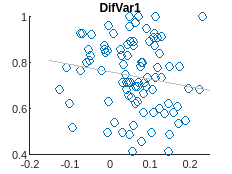

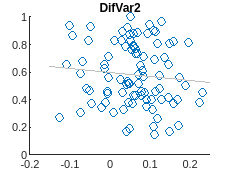

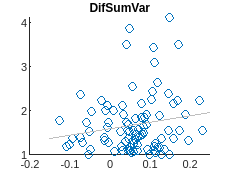

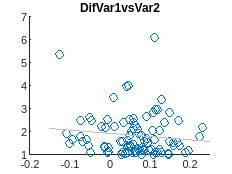

BD


                      group1      group2      sumGroup    group1vsGroup2
                     ________    _________    ________    ______________

    spearman corr    -0.18511    -0.085241    0.10047       -0.092033   
    p                0.075017      0.26134    0.23868         0.28549   



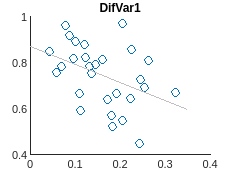

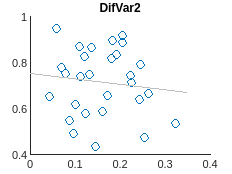

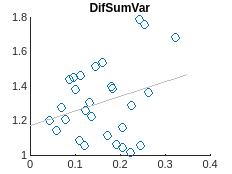

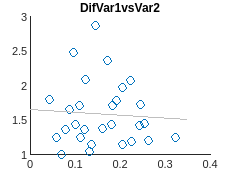

SCA


                      group1      group2      sumGroup    group1vsGroup2
                     ________    _________    ________    ______________

    spearman corr    -0.39803    -0.066229    0.10892        -0.0104    
    p                0.043604      0.38781    0.29415        0.45361    



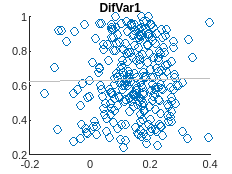

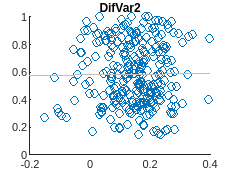

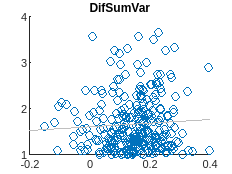

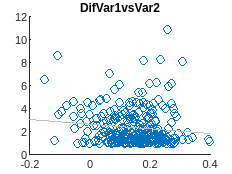

SCZ


                      group1       group2      sumGroup    group1vsGroup2
                     _________    _________    ________    ______________

    spearman corr    0.0014749    -0.015856    0.061431       -0.11334   
    p                  0.47408      0.45188     0.23804        0.15682   



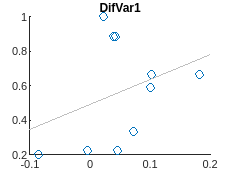

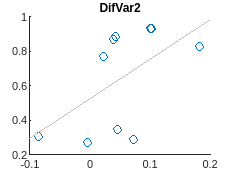

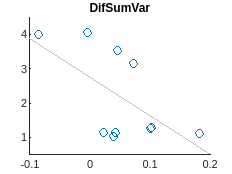

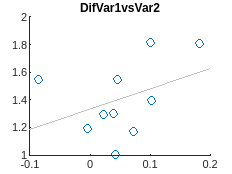

ASD


                     group1      group2     sumGroup    group1vsGroup2
                     _______    ________    ________    ______________

    spearman corr    0.20184     0.53939    -0.38182        0.34545   
    p                0.39456    0.067105     0.15497       0.084718   



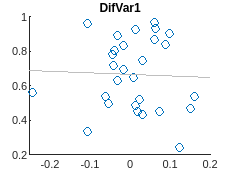

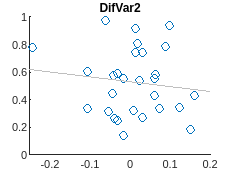

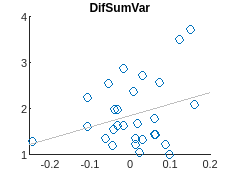

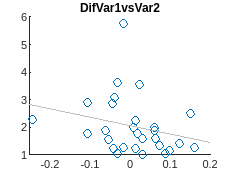

MDD


                      group1       group2      sumGroup    group1vsGroup2
                     _________    _________    ________    ______________

    spearman corr    -0.055829    -0.044882    0.14067        -0.35796   
    p                  0.45068      0.44813    0.25395        0.085785   



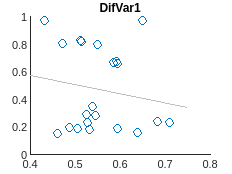

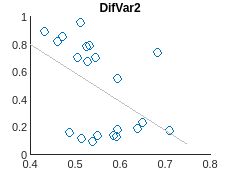

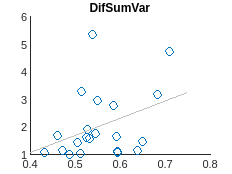

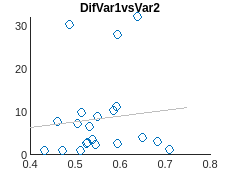

AD


                      group1       group2     sumGroup    group1vsGroup2
                     _________    ________    ________    ______________

    spearman corr    -0.079221    -0.44156    0.30909            0.2    
    p                  0.34921     0.05547    0.18072        0.22256    




% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to patient number similarity between sites
    [varTable{iDiag} patientRatio{iDiag} controlRatio{iDiag} subjectRatio{iDiag} patientControlRatio{iDiag} nSite{iDiag}]= cor_var_nPC(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag}, iter, type);
% Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

% Save results to a .mat file
save('output/confound_nPC.mat','varTable', 'patientRatio', 'controlRatio', 'subjectRatio', 'patientControlRatio','nSite')